# Marginal cost data analysis

## Load marginal cost data

% You have to run this under model_code directory
MCFileDir = "../model_output/";
MCFileName = "MC_*.csv";
MCDataStore = fileDatastore(MCFileDir + MCFileName, "ReadFcn", @importMarginalCost, "UniformRead", true);
MCAll = readall(MCDataStore);
clear MCDataStore;

numTopParts = 10;
rankedParts = sortrows(groupsummary(MCAll, "PartID"), "GroupCount", "descend")

rankedParts = 43×2 table
      PartID      GroupCount
    __________    __________

    2.0685e+05       3533   
    4.0159e+05       3478   
    2.1249e+05       3110   
    5.9198e+05       3083   
    9.0279e+05       2973   
    5.9564e+05       2507   
    8.7279e+05       2292   
    9.5851e+05       2120   
    3.2872e+05       1837   
    2.1984e+05       1795   
    5.0417e+05       1344   
    7.3974e+05       1226   
    7.4967e+05       1197   
    6.9895e+05        811   
    2.9245e+05        599   
    2.9553e+05        588   


topPartIDs = rankedParts.PartID(1:numTopParts)

topPartIDs =       206845
      401592
      212494
      591975
      902793
      595644
      872788
      958512
      328723
      219842


topPartQMCTables = cell(size(topPartIDs));
for n = 1:size(topPartIDs, 1)
    topPartQMCTables{n} = MCAll(MCAll.PartID == topPartIDs(n), :);
end

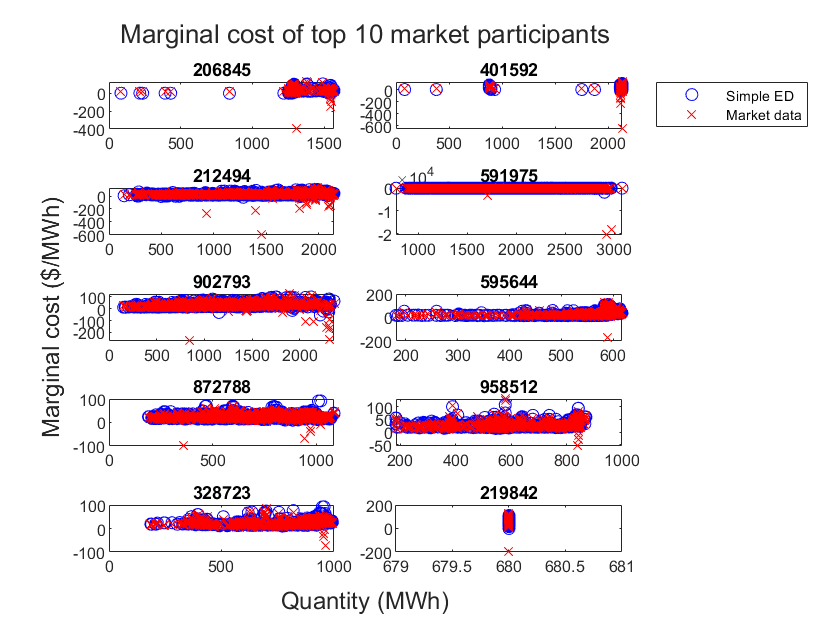

t = tiledlayout(numTopParts/2, 2, "TileSpacing","compact");
for n = 1:size(topPartIDs, 1)
    nexttile;
    partQMCTable = topPartQMCTables{n};
    partID = topPartIDs(n);
    scatter(partQMCTable.Awarded, partQMCTable.MCSimpleED, 'bo');
    hold on;
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    if n==2
        legend(["Simple ED", "Market data"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Marginal cost of top 10 market participants");

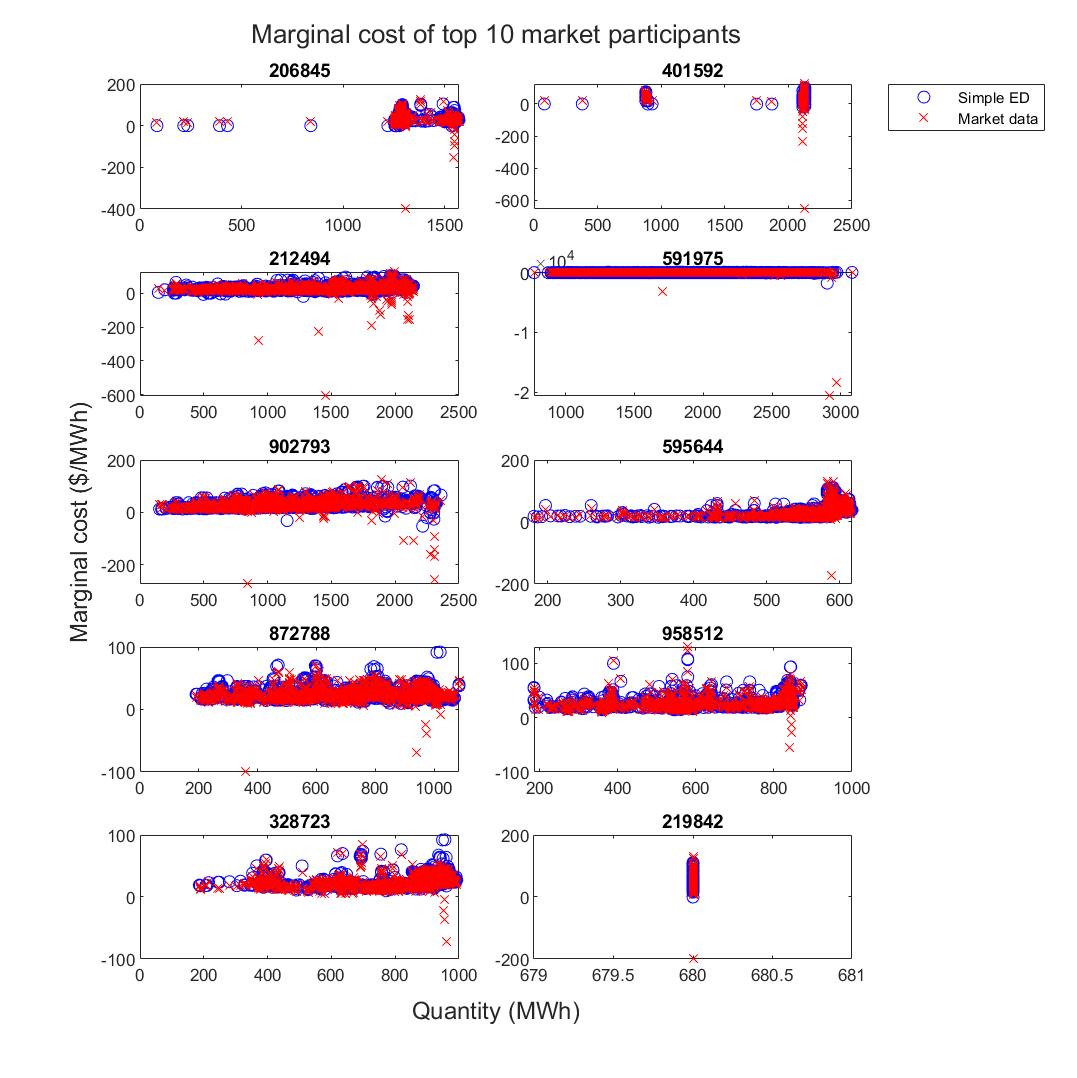

set(gcf, "Position", [100, 100, 900, 900]);

partQMCTable = topPartQMCTables{3}

partQMCTable = 3110×6 table
       Date       Hour      PartID      Awarded    MCSimpleED    MCMarket
    __________    ____    __________    _______    __________    ________

    03/22/2019      2     2.1249e+05     317.5       24.321       18.421 
    03/22/2019      3     2.1249e+05     317.5        24.32       18.383 
    03/22/2019      4     2.1249e+05       317       24.329        18.57 
    03/22/2019      5     2.1249e+05       317       26.398       22.772 
    03/22/2019      6     2.1249e+05     316.5        29.49       30.429 
    03/22/2019      7     2.1249e+05     883.5       27.465       30.498 
    03/22/2019      8     2.1249e+05    1353.5       26.351       25.768 
    03/22/2019      9     2.1249e+05    1404.5       26.257       35.714 
    03/22/2019     10     2

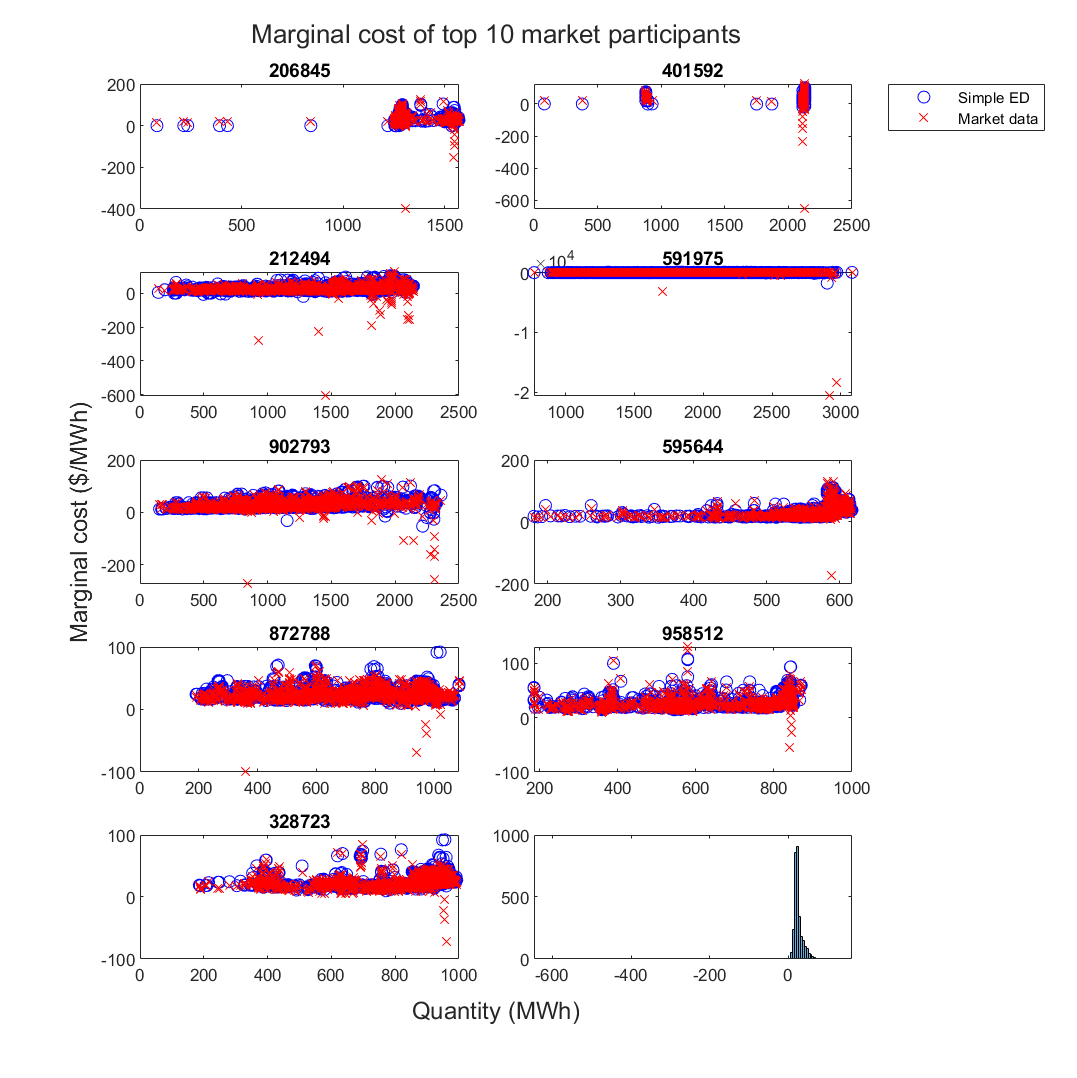

histogram(partQMCTable.MCMarket)

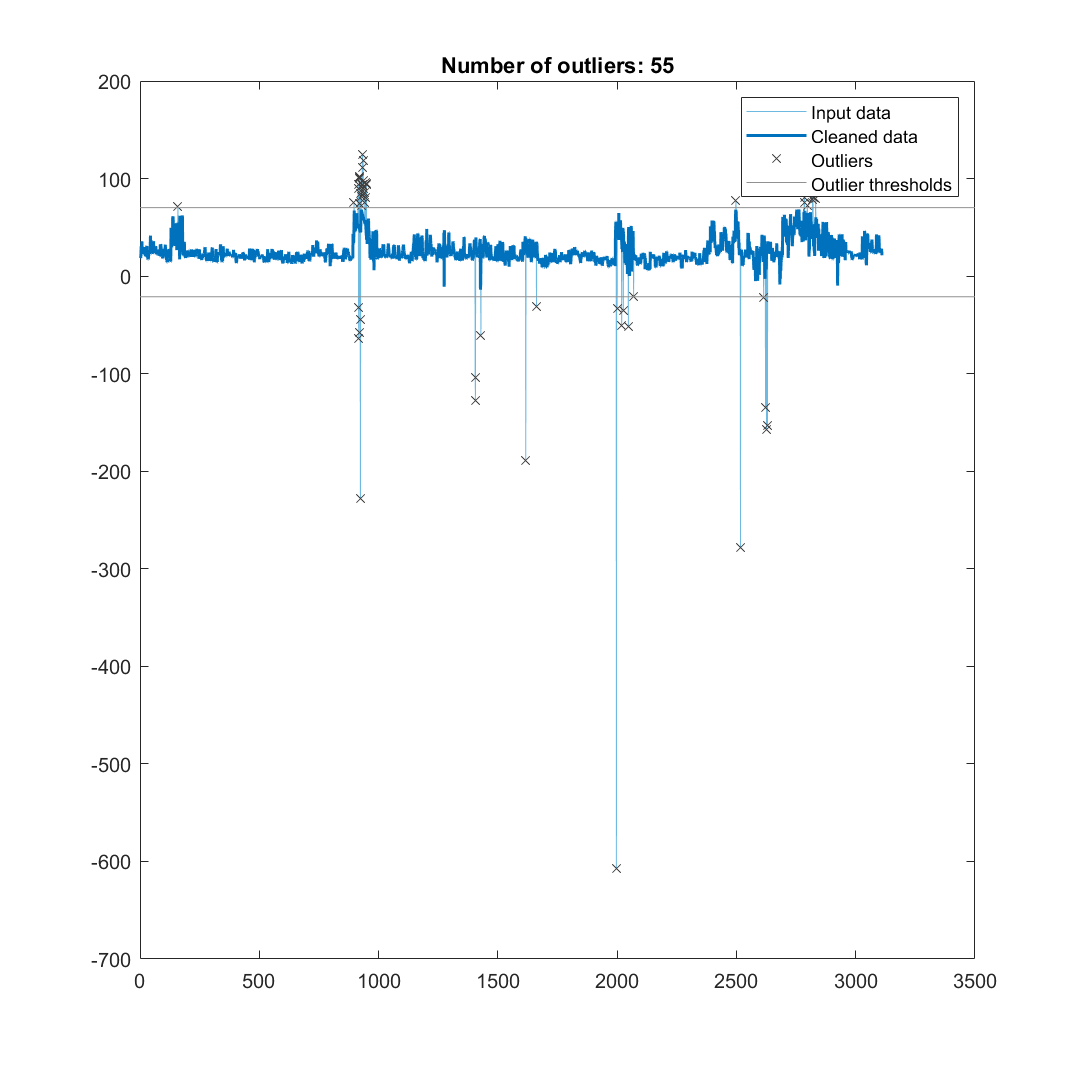

% Remove outliers
[cleanedPrice,outlierIndices] = rmoutliers(partQMCTable.MCMarket,'gesd');

% Display results
clf
plot(partQMCTable.MCMarket,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on
plot(find(~outlierIndices),cleanedPrice,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices),partQMCTable.MCMarket(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Compute thresholds and center
[~,thresholdLow,thresholdHigh] = isoutlier(partQMCTable.MCMarket,'gesd');

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear thresholdLow thresholdHigh
cleanedPartQMCTable = partQMCTable(~outlierIndices, :)

cleanedPartQMCTable = 3055×6 table
       Date       Hour      PartID      Awarded    MCSimpleED    MCMarket
    __________    ____    __________    _______    __________    ________

    03/22/2019      2     2.1249e+05     317.5       24.321       18.421 
    03/22/2019      3     2.1249e+05     317.5        24.32       18.383 
    03/22/2019      4     2.1249e+05       317       24.329        18.57 
    03/22/2019      5     2.1249e+05       317       26.398       22.772 
    03/22/2019      6     2.1249e+05     316.5        29.49       30.429 
    03/22/2019      7     2.1249e+05     883.5       27.465       30.498 
    03/22/2019      8     2.1249e+05    1353.5       26.351       25.768 
    03/22/2019      9     2.1249e+05    1404.5       26.257       35.714 
    03/22/2019     1

cleanedPrice = cleanedPartQMCTable.MCMarket;
cleanedQuantity = cleanedPartQMCTable.Awarded;
partLM = fitlm(cleanedQuantity, cleanedPrice)

partLM = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue   
                   _________    __________    ______    ___________

    (Intercept)        16.17       0.50488    32.027    2.6757e-194
    x1             0.0063256    0.00035633    17.752     3.5354e-67


Number of observations: 3055, Error degrees of freedom: 3053
Root Mean Squared Error: 10.1
R-squared: 0.0936,  Adjusted R-Squared: 0.0933
F-statistic vs. constant model: 315, p-value = 3.54e-67

coeffLM = partLM.Coefficients.Estimate

coeffLM =    16.1699
    0.0063


partPoly2 = polyfit(cleanedQuantity, cleanedPrice, 2);
partPoly3 = polyfit(cleanedQuantity, cleanedPrice, 3);
x = 0:2500;
pricePoly2 = polyval(partPoly2, x);
pricePoly3 = polyval(partPoly3, x);
priceLM = x*coeffLM(2) + coeffLM(1);

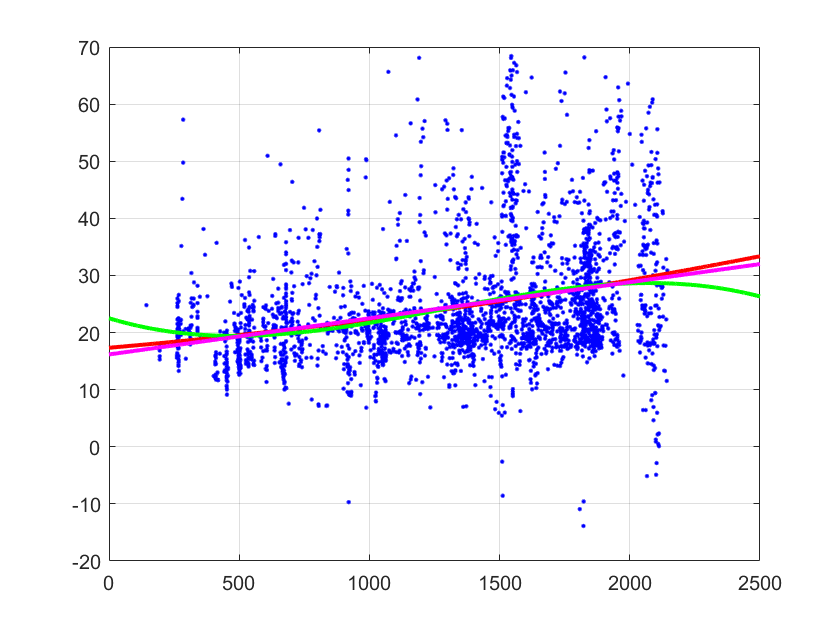

figure;
scatter(cleanedPartQMCTable.Awarded, cleanedPartQMCTable.MCMarket, 'b.');
hold on;
plot(x, pricePoly2, 'r', 'LineWidth',2);
plot(x, pricePoly3, 'g', 'LineWidth',2);
plot(x, priceLM, 'm', 'LineWidth',2);
hold off; box on; grid on;

## Fit polynomial relation between marginal cost and quantity

% polyOrder = 2;
% topPartMCPoly = zeros(numTopParts, polyOrder);
% for n = 1:size(topPartIDs, 1)
%     partQMCTable = topPartQMCTables{n};
%     partID = topPartIDs(n);
%     MCPoly = polyfit(partQMCTable.Awarded, partQMCTable.MCSimpleED, polyOrder);
%     topPartMCPoly(n, :) = MCPoly;
% end
% topPartMCPoly 

## Read Data

load('selCleanedPartQMCTables.mat');
plot_data = cell(8,2);
parameter = [];

## CVX linear

for i = 1:8
    cleanedPrice = selCleanedPartQMCTables{i}.cleanedMedian_MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{i}.Awarded;
    plot_data{i,1} = cleanedQuantity;
    plot_data{i,2} = cleanedPrice;
    cvx_begin 
        variable A
        variable b
        minimize( norm( cleanedPrice-(A*cleanedQuantity+b)) );
        cvx_end
    parameter = [parameter;[A b]];
end

 
Calling SDPT3 4.0: 1436 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of socp   var  = 1436,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|5.8e+01|2.2e+06| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|5.8e-04|1.0e-04|5.5e+04|-2.653580e+00 -5.490250e+04| 0:0:00| chol  1  1 
 2|1.000|0.984|6.1e-08|1.3e-04|8.9e+02|-5.451992e+00 -8.967581e+02| 0:0:00| chol  1  1 
 3|1.000|0.822|1.8e-08|2.4e-05|1.3e+02|-1.666407e+02 -2.9677

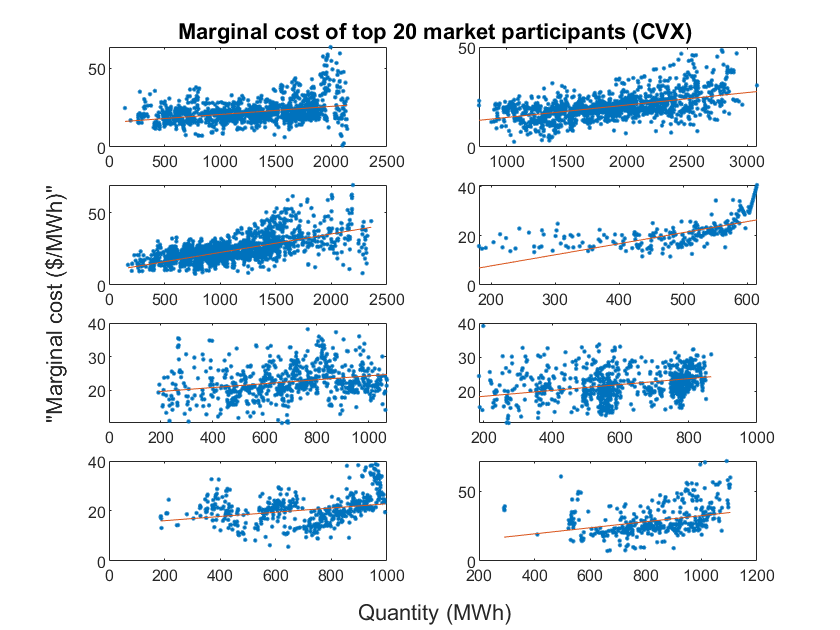

cvx_y = 8×1 cell array
    {1866×1 double}
    {1849×1 double}
    {1970×1 double}
    {1505×1 double}
    {1376×1 double}
    {1272×1 double}
    {1103×1 double}
    { 719×1 double}


cvx_y = multiplot(plot_data, parameter,8, 1)

## RMSE

corrQuad = zeros(8, 1);
RMSEQuad = zeros(8, 1);
for n=1:8
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    cvx_pre = cvx_y{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, cvx_pre);
    corrQuad(n)= quadR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean((partCleanedQMCTable.MCMarket-cvx_pre).^2));
end
selPartCorrTable = table(corrQuad, RMSEQuad)

selPartCorrTable = 8×2 table
    corrQuad    RMSEQuad
    ________    ________

     0.3772      6.4579 
    0.51311      5.0826 
    0.63589      6.4023 
    0.54499      4.5208 
     0.2761      4.5942 
    0.36818      4.4895 
    0.32277      4.8198 
     0.3311      9.9009 


## Quad

plot_data = cell(8,2);
parameter = [];
for i = 1:8
    cleanedPrice = selCleanedPartQMCTables{i}.cleanedMedian_MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{i}.Awarded;
    plot_data{i,1} = cleanedQuantity;
    plot_data{i,2} = cleanedPrice;
    cvx_begin 
        variable A
        variable B
        variable C
        minimize( norm( cleanedPrice-(A*cleanedQuantity.^2+B*cleanedQuantity+C)) );
        cvx_end
        parameter = [parameter;[A B C]];
end

 
Calling SDPT3 4.0: 1436 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  = 1436,   num. of socp blk  =  1
 number of nearly dependent constraints = 2
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|9.5e+04|3.6e+09| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|5.4e-04|1.0e-04|8.9e+07|-1.573009e-03 -8.919328e+07| 0:0:00| chol  1  1 
 2|1.000|0.989|6.1e-08|1.2e-04

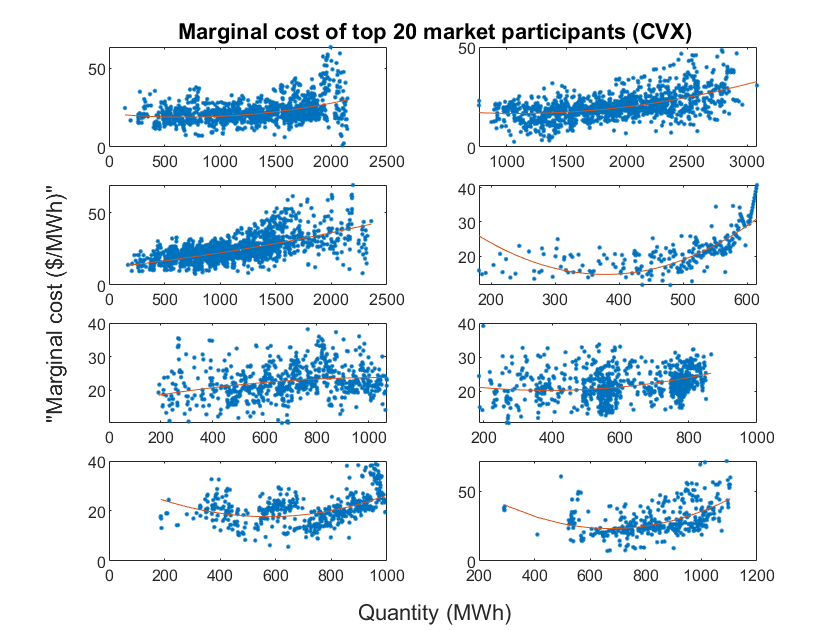

% PLOT
cvx_y = multiplot(plot_data, parameter, 8, 2);

## RMSE

corrQuad = zeros(8, 1);
RMSEQuad = zeros(8, 1);
for n=1:8
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    cvx_pre = cvx_y{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, cvx_pre);
    corrQuad(n)= quadR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean((partCleanedQMCTable.MCMarket-cvx_pre).^2));
end
selPartCorrTable = table(corrQuad, RMSEQuad)

selPartCorrTable = 8×2 table
    corrQuad    RMSEQuad
    ________    ________

    0.41859      6.3327 
    0.53965      4.9854 
    0.63816      6.3867 
    0.68823      3.9562 
    0.28314      4.5844 
    0.41218      4.4081 
    0.46269      4.5149 
     0.4991      9.0963 


## Cubic CVX

plot_data = cell(8,2);
parameter = [];
for i = 1:8
    cleanedPrice = selCleanedPartQMCTables{i}.cleanedMedian_MCMarket;
    cleanedQuantity = selCleanedPartQMCTables{i}.Awarded;
    plot_data{i,1} = cleanedQuantity;
    plot_data{i,2} = cleanedPrice;
    cvx_begin 
        variable A
        variable B
        variable C
        variable D
        minimize( norm( cleanedPrice-(A*cleanedQuantity.^3+B*cleanedQuantity.^2+C*cleanedQuantity + D)) );
    cvx_end
    parameter = [parameter;[A B C D]];
end

 
Calling SDPT3 4.0: 1436 variables, 5 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  5
 dim. of socp   var  = 1436,   num. of socp blk  =  1
 number of nearly dependent constraints = 3
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.8e+01|1.7e+08|6.2e+12| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|5.0e-04|1.0e-04|1.6e+11|-9.263400e-07 -1.562047e+11| 0:0:00| chol  2  2 
 2|1.000|0.989|6.1e-08|1.1e-04

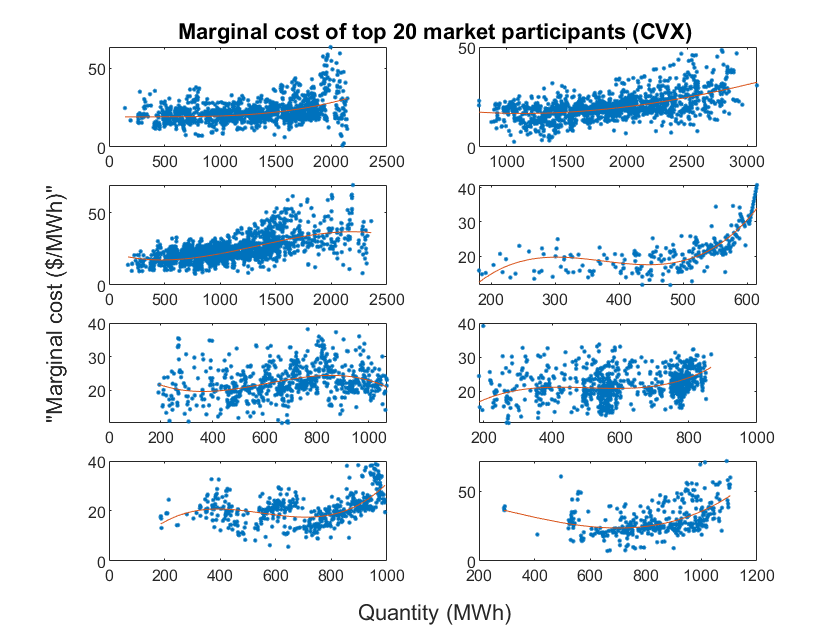

% PLOT
cvx_y = multiplot(plot_data, parameter, 8, 3);

## RMSE

corrQuad = zeros(8, 1);
RMSEQuad = zeros(8, 1);
for n=1:8
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    cvx_pre = cvx_y{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, cvx_pre);
    corrQuad(n)= quadR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean((partCleanedQMCTable.MCMarket-cvx_pre).^2));
end
selPartCorrTable = table(corrQuad, RMSEQuad)

selPartCorrTable = 8×2 table
    corrQuad    RMSEQuad
    ________    ________

    0.41977      6.3289 
    0.53973      4.9851 
    0.64986       6.305 
    0.72826      3.7551 
    0.33931      4.4965 
    0.46572      4.2967 
     0.5665      4.1974 
    0.50223      9.0774 
